# Peltier Split

Split the temperature response into seperate traces for each trial, and split the stimulation file into plot

temperature = [35, 25, 20, 40, 15, 45, 10, 50, 5, 55];
T = readtable(fullfile(path, filename));
n = size(T, 1)/10;
for i = 1:10
    Tsplit = T(1+n*(i-1):i*n,:);
    writetable(Tsplit, fullfile(path, ['peltier_', num2str(temperature(i)),'C.csv']));
end

Calibration

T = [0.8, 10.63, 25.63, 37.36, 41.31, 45.15, 59.37]; % Y
mV = [-55, 43, 193, 314, 353, 395, 547]; % X 
V = mV/1000;
X =  [ones(length(mV),1) V'];
b0 = X\T';
% TC = b0(1)+b0(2)*X;
% figure
% scatter(V,T)
% hold on
% plot(V,TC(:,2))

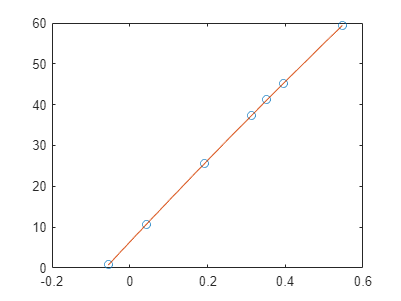

[p, S] = polyfit(V, T, 2);
V1 = linspace(min(V), max(V));

TC = polyval(p, V1);
figure
plot(V,T,'o')
hold on
plot(V1,TC)
hold off

% celsius = -(data-(-0.1641))/0.0105+ 23;
% celsius =b0(2)*(data *-1)+b0(1);
celsius = polyval(p, data*(-1))
b = reshape(celsius, [numel(celsius)/10, 10]);
downs = 20; 
delay = 4.1;
b = b(Fs*delay+1:downs:Fs*(60+delay),:);

c = zeros(size(b));
temperatureSorted = [5, 10, 15, 20, 25, 35, 40, 45, 50, 55];
slope = 5; %5 celsius per second
baseline = 32;
fps = 10;
cpf = slope/Fs*downs; %
% celsius per datapiont
for i = 1:10
    rampPoint = abs((temperatureSorted(i)-baseline)/cpf);
    c(1:20*Fs/downs,i) = baseline;    
    c(20*Fs/downs:20*Fs/downs+rampPoint,i) = baseline:(temperatureSorted(i)-baseline)/rampPoint:temperatureSorted(i);
    c(20*Fs/downs+rampPoint+1:40*Fs/downs,i) = temperatureSorted(i);
    c(40*Fs/downs:40*Fs/downs+rampPoint,i) = temperatureSorted(i):(baseline-temperatureSorted(i))/rampPoint:baseline;
    c(40*Fs/downs+rampPoint+1:60*Fs/downs,i) = baseline;
    %    a(600*(i-1)+401+rampFrame*2:600*i-gap) = baseline;
%     a(600*i-gap+1:600*i) =NaN;    
end
% figure, plot(movmedian(a, 20), 'color',[0.4, 0.4, 0.4]);
figure, 
set(gcf,'Visible','on')
plot(movmedian(b, 20), 'LineWidth',1, 'color', [0, 0.5, 1, 0.6]);
hold on
plot(c, 'LineWidth',2, 'color', [1, 0.3, 0, 0.6]);
box off
axis off
timeBar = 5; % scale bar for time is 5 seconds
thermalBar = 5; % scale bar for temperature is 5 celsus
line([1*Fs/downs,(1+timeBar)*Fs/downs],[45, 45],'Color',[0.5, 0.5, 0.5])
line([1*Fs/downs, 1*Fs/downs],[45, 50],'color',[0.5, 0.5, 0.5])
% exportgraphics(gcf,['E:\Dropbox (HMS)\RIG_DATA\Second Paper\LQ_figure\polymodality\', ...
%    'thermal_stimuli_command vs real.jpg'],'Resolution',600);

a = zeros(6000, 1);
baseline = 32;
temperatureSorted = [5, 10, 15, 20, 25, 35, 40, 45, 50, 55];
gap = 50;
slope = 5; %5 celsius per second
fps = 10;
cpf = slope/fps; % celsius per frame
for i = 1:10
    rampFrame = abs((temperatureSorted(i)-baseline)/cpf);
    a(600*(i-1)+1:600*(i-1)+gap) = NaN;
    a(600*(i-1)+gap+1:600*(i-1)+200) = baseline;    
    a(600*(i-1)+200:600*(i-1)+200+rampFrame) = baseline:(temperatureSorted(i)-baseline)/rampFrame:temperatureSorted(i);
    a(600*(i-1)+201+rampFrame:600*(i-1)+400) = temperatureSorted(i);
    a(600*(i-1)+400:600*(i-1)+400+rampFrame) = temperatureSorted(i):(baseline-temperatureSorted(i))/rampFrame:baseline;
    a(600*(i-1)+401+rampFrame:600*i) = baseline;
    %    a(600*(i-1)+401+rampFrame*2:600*i-gap) = baseline;
%     a(600*i-gap+1:600*i) =NaN;    
end
figure('units','inch',"Position", [1, 1, 3.2, 0.32]);
set(gcf,'Visible','on')
plot(a, 'LineWidth',0.5,'Color','black')
box off
axis off
ax = gca;
ax.Position = ax.OuterPosition;
exportgraphics(gcf,['E:\Dropbox (HMS)\RIG_DATA\Second Paper\LQ_figure\polymodality\', ...
    'thermal_stimuli_new.jpg'],'Resolution',600);

a = zeros(6000, 1);
baseline = 32;
temperatureSorted = [5, 10, 15, 20, 25, 35, 40, 45, 50, 55];
gap = 50;
slope = 5; %5 celsius per second
fps = 10;
cpf = slope/fps; % celsius per frame
for i = 1:10
    rampFrame = abs((temperatureSorted(i)-baseline)/cpf);
    a(600*(i-1)+1:600*(i-1)+gap) = NaN;
    a(600*(i-1)+gap+1:600*(i-1)+200) = baseline;    
    a(600*(i-1)+200:600*(i-1)+200+rampFrame) = baseline:(temperatureSorted(i)-baseline)/rampFrame:temperatureSorted(i);
    a(600*(i-1)+201+rampFrame:600*(i-1)+400) = temperatureSorted(i);
    a(600*(i-1)+400:600*(i-1)+400+rampFrame) = temperatureSorted(i):(baseline-temperatureSorted(i))/rampFrame:baseline;
    a(600*(i-1)+401+rampFrame:600*i) = baseline;
    %    a(600*(i-1)+401+rampFrame*2:600*i-gap) = baseline;
%     a(600*i-gap+1:600*i) =NaN;    
end
b = zeros(6050,1);
b(1:3000) = a(1:3000);
b(3001:3050) = nan;
b(3051:end) = a(3001:6000);
figure('units','inch',"Position", [1, 1, 4.70, 0.16]);
set(gcf,'Visible','on')
plot(b, 'Color','black')
box off
axis off
ax = gca;
ax.Position = ax.OuterPosition;
exportgraphics(gcf,['E:\Dropbox (HMS)\RIG_DATA\Second Paper\LQ_figure\polymodality\', ...
    'thermal_stimuli_tall.jpg'],'Resolution',600);

digitalData = zeros(size(data));
digitalData(data>1) = 1; % binarize the data
% data(data<1) = 0;
change = diff(digitalData);
riseTime = find(change == -1)/Fs;
backTime = find(change == 1)/Fs;
if sum(digitalData(end-100:end)) > 0 % when the peltier reaches stable temeperature in 10s
    startTime = riseTime(1) - 20;
    startTime2 = backTime(end) - 900;
    if abs(startTime - startTime2)<1
        realStartTime = (startTime+startTime2)/2;
    else
        error('something wrong with the data')
    end
else
    realStartTime = riseTime(2)- 20; % when there is disruption to the peltier, taking it longer to reach stable state
end
